clear;
A=sym("A","positive");
a=sym('a','positive');
lambda=sym('lambda','positive');
x=sym('x','real');

rho(x)=A*exp(-lambda*(x-a)^2)

$$rho(x) = A\,{\mathrm{e}}^{-\lambda \,{\left(a-x\right)}^{2}}$$


Asoln=solve(int(rho(x),x,-inf,inf)==1,A)

$$Asoln = \frac{\sqrt{\lambda }}{\sqrt{\pi }}$$

rhonorm(x)=subs(rho(x),A,Asoln);

xavg=simplify(int(x*rhonorm(x),x,-inf,inf))

$$xavg = a$$

x2avg=simplify(int(x^2*rhonorm(x),x,-inf,inf))

$$x2avg = a^{2}+\frac{1}{2\,\lambda }$$


stdev=sqrt(x2avg-xavg^2)

$$stdev = \frac{\sqrt{2}}{2\,\sqrt{\lambda }}$$

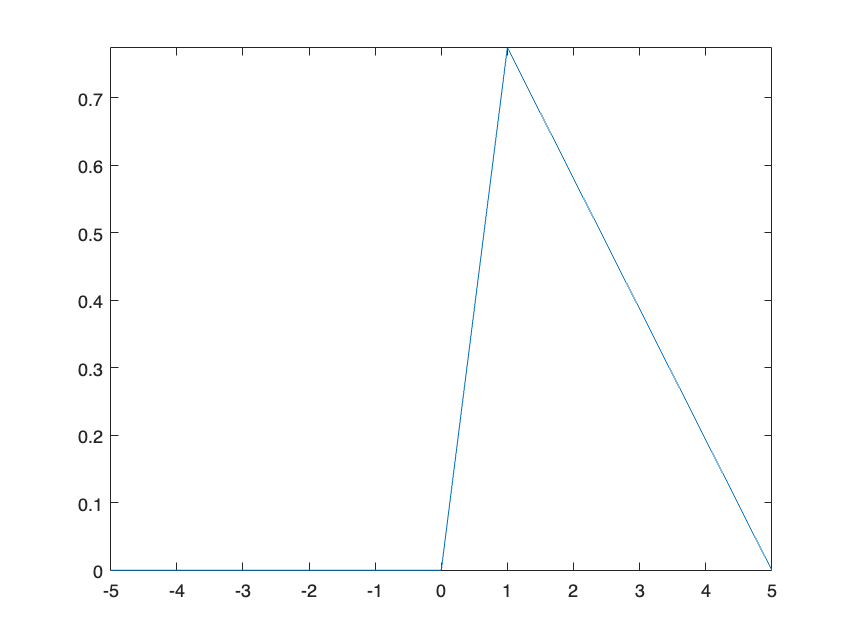


graph(x)=subs(rhonorm(x),[a,lambda],[0,5]);
fplot(graph(x))

clear;
A=sym('A','positive');
a=sym('a','positive');
b=sym('b','positive');
x=sym('x','real');
assume(a<b);
assumeAlso(a>0);
assumeAlso(b>0);

psi(x)=piecewise((0<=x)&(x<=a), A*x/a, (a<x)&(x<b), A*(b-x)/(b-a),0)

$$psi(x) = \left\{ \begin{array}{cl} \frac{A\,x}{a} & \text{ if }x\leq a\wedge 0\leq x\\ -\frac{A\,\left(b-x\right)}{a-b} & \text{ if }a<x\wedge x<b\\ 0 & \mathrm{otherwise} \end{array}\right.$$


psiSoln=solve(int(conj(psi(x))*psi(x),x,0,b)==1,A)

$$psiSoln = \frac{\sqrt{3}}{\sqrt{b}}$$

psiNorm(x)=subs(psi(x),A,psiSoln);

psiGraph(x)=subs(psiNorm(x),[a,b],[1,5]);
fplot(psiGraph(x))


psiL=int(conj(psiNorm(x))*psiNorm(x),x,0,a)

$$psiL = \frac{a}{b}$$


avgx=simplify(int(x*conj(psiNorm(x))*psiNorm(x),x,0,b))

$$avgx = \frac{a}{2}+\frac{b}{4}$$

clear;
A=sym('A','positive');
lambda=sym('lambda','positive');
omega=sym('omega','positive');
x=sym('x','real');
t=sym('t','real');

psi(x,t)=A*exp(-lambda*abs(x))*exp(-i*omega*t)

$$psi(x, t) = A\,{\mathrm{e}}^{-\lambda \,\left|x\right|}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}$$

Asoln=solve(int(conj(psi(x,t))*psi(x,t),x,-inf,inf)==1,A); %If t=1, then Asoln=sqrt(lambda), which is true for all values of t.

psiNorm(x,t)=subs(psi(x,t),A,Asoln);

xavg=simplify(int(x*conj(psiNorm(x,t))*psiNorm(x,t),x,-inf,inf))

$$xavg = 0$$

x2avg=simplify(int(x^2*conj(psiNorm(x,t))*psiNorm(x,t),x,-inf,inf))

$$x2avg = \frac{1}{2\,\lambda^{2}}$$


stdev=sqrt(x2avg-xavg^2)

$$stdev = \frac{\sqrt{2}}{2\,\lambda }$$


psiGraph(x)=subs(psiNorm(x,t),[lambda,omega,t],[1,0,0])

$$psiGraph(x) = {\mathrm{e}}^{-\left|x\right|}$$

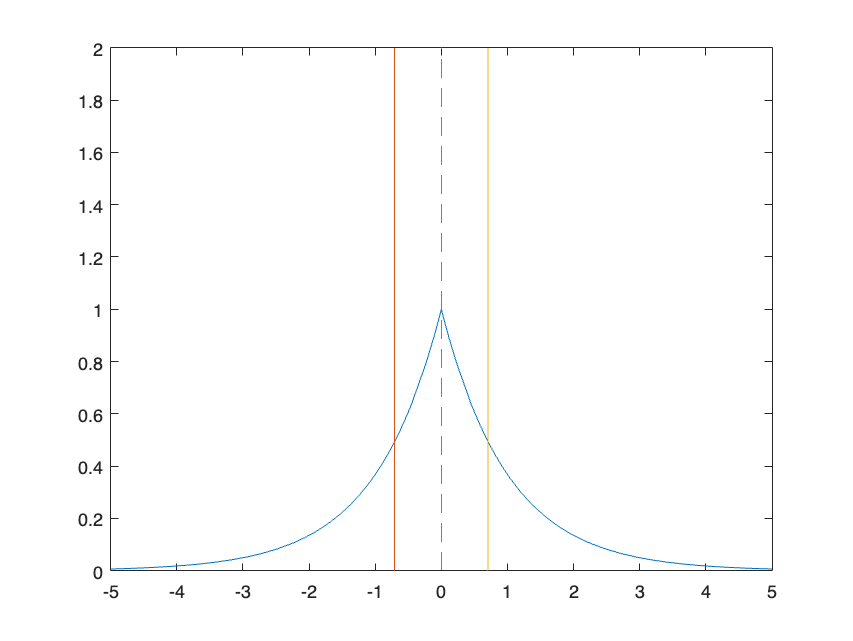

fplot(psiGraph)
hold on;
stdevPlot=vpa(subs(stdev,lambda,1));
plot([-stdevPlot,-stdevPlot],[0,2]);
plot([stdevPlot,stdevPlot],[0,2]);
hold off;


prob_in=vpa(int(psiNorm(x,0)^2,x,-stdev,stdev))

$$prob\_in = 0.75688326556578578919513767950005$$

prob_out=1-prob_in

$$prob\_out = 0.24311673443421421080486232049995$$

clear;
A=sym('A','positive');
a=sym('a','positive');
m=sym('m','positive');
hbar=sym('hbar','positive');
t=sym('t','real');
x=sym('x','real');

psi(x,t)=A*exp(-a*((m*x^2)/hbar+i*t))

$$psi(x, t) = A\,{\mathrm{e}}^{-a\,\left(\frac{m\,x^{2}}{\mathrm{hbar}}+t\,\mathrm{i}\right)}$$

Asoln=solve(int(conj(psi(x,0))*psi(x,0),x,-inf,inf)==1,A)

$$Asoln = \frac{2^{1/4}\,a^{1/4}\,m^{1/4}}{{\mathrm{hbar}}^{1/4}\,\pi^{1/4}}$$

psiNorm(x,t)=subs(psi(x,t),A,Asoln);

syms V(x)
Vx=sym('Vx','positive');
SEqtn = -hbar^2/(2*m)*diff(psiNorm(x,t),x,2) + Vx*psiNorm(x,t) == 1i*hbar*diff(psiNorm(x,t),t);
V(x)=solve(SEqtn,Vx)

$$V(x) = 2\,a^{2}\,m\,x^{2}$$


xavg=simplify(int(x*conj(psiNorm(x,t))*psiNorm(x,t),x,-inf,inf))

$$xavg = 0$$

x2avg=simplify(int(x^2*conj(psiNorm(x,t))*psiNorm(x,t),x,-inf,inf))

$$x2avg = \frac{\mathrm{hbar}}{4\,a\,m}$$

pavg=simplify(int(conj(psiNorm(x,t))*hbar/1i*diff(psiNorm(x,t),x),x,-inf,inf))

$$pavg = 0$$

p2avg=simplify(int(conj(psiNorm(x,t))*(hbar/1i)^2*diff(psiNorm(x,t),x,2),x,-inf,inf))

$$p2avg = a\,\mathrm{hbar}\,m$$


stdevX=sqrt(x2avg-xavg^2)

$$stdevX = \frac{\sqrt{\mathrm{hbar}}}{2\,\sqrt{a}\,\sqrt{m}}$$

stdevP=sqrt(p2avg-pavg^2)

$$stdevP = \sqrt{a}\,\sqrt{\mathrm{hbar}}\,\sqrt{m}$$

stdevX*stdevP<=hbar/2

$$ans = \frac{\mathrm{hbar}}{2}\leq \frac{\mathrm{hbar}}{2}$$